Loads handle and seat acceleration and orientation data.

handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");

Defines time ranges of clean data for good and bad erg strokes.

good_range = timerange('29-Nov-2022 16:50:20.008','29-Nov-2022 16:50:35.719','closed');
bad_range = timerange('29-Nov-2022 16:50:44.103','29-Nov-2022 16:50:54.863','closed');

Trims acceleration data into defined ranges.

handle.Acceleration_Good = handle.Acceleration(good_range, :);
seat.Acceleration_Good = seat.Acceleration(good_range, :);
handle.Acceleration_Bad = handle.Acceleration(bad_range, :);
seat.Acceleration_Bad = seat.Acceleration(bad_range, :);

Integrates acceleration data to create sets of velocity data.

handle.Velocity_Good = timetable(handle.Acceleration_Good.Timestamp, cumtrapz(handle.Acceleration_Good.X), 'VariableNames',{'Handle'});
seat.Velocity_Good = timetable(seat.Acceleration_Good.Timestamp, cumtrapz(seat.Acceleration_Good.Y), 'VariableNames',{'Seat'});

handle.Velocity_Bad = timetable(handle.Acceleration_Bad.Timestamp, cumtrapz(handle.Acceleration_Bad.X), 'VariableNames',{'Handle'});
seat.Velocity_Bad = timetable(seat.Acceleration_Bad.Timestamp, cumtrapz(seat.Acceleration_Bad.Y), 'VariableNames',{'Seat'});

Synchronizes and interpolates handle and seat timetables to create one merged dataset.

velocity_sync_good = synchronize(handle.Velocity_Good, seat.Velocity_Good, 'union', 'linear');
velocity_sync_bad = synchronize(handle.Velocity_Bad, seat.Velocity_Bad, 'union', 'linear');

Converts datetime from timetables into an elapsed time vector in seconds.

normal_time_good = velocity_sync_good.Time.Second - velocity_sync_good.Time.Second(1,:);
normal_time_bad = velocity_sync_bad.Time.Second - velocity_sync_bad.Time.Second(1,:);

Normalizes each dataset based on a hard-coded slope value to negate the effects of creep in the data (introduced as a result of the integration process).

normal_seat_good = velocity_sync_good.Seat - (153.347/12.377)*normal_time_good;
normal_handle_good = velocity_sync_good.Handle - (-275.964/7.127)*normal_time_good;

normal_seat_bad = velocity_sync_bad.Seat - (67.1946/7.75)*normal_time_bad;
normal_handle_bad = velocity_sync_bad.Handle - (-499.118/6.488)*normal_time_bad;

Combines normalized time and velocity vectors into a good and bad array.

velo_normal_good = [normal_time_good normal_seat_good normal_handle_good];
velo_normal_bad = [normal_time_bad normal_seat_bad normal_handle_bad];

Plots both good and bad velocity arrays, with seat and handle data side by side.

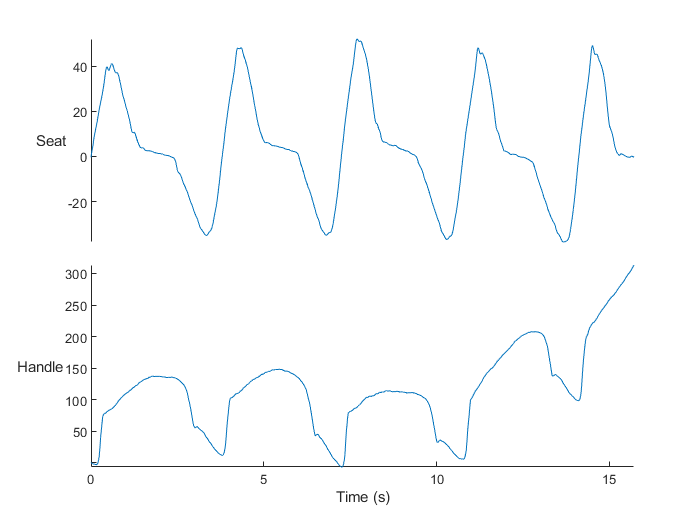

figure(2);
stackedplot(velo_normal_good(:,1), velo_normal_good(:,2:3), 'XLabel','Time (s)', 'DisplayLabels', {'Seat', 'Handle'})

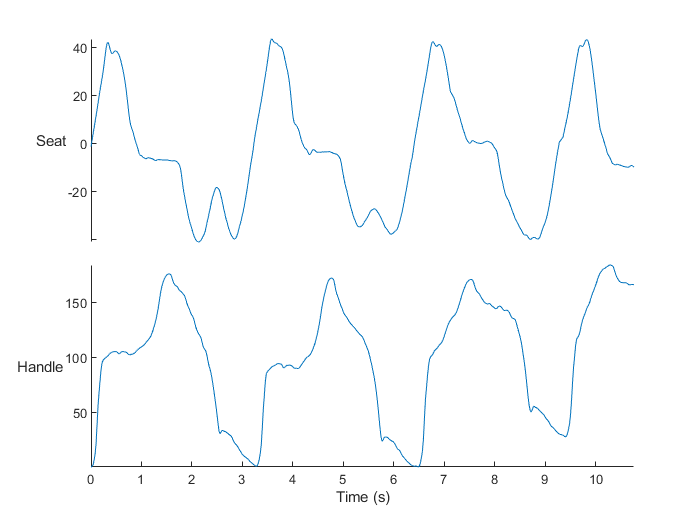


figure(3);
stackedplot(velo_normal_bad(:,1), velo_normal_bad(:,2:3), 'XLabel','Time (s)', 'DisplayLabels', {'Seat', 'Handle'})

Finds the DFT of the velocity good and bad handle data

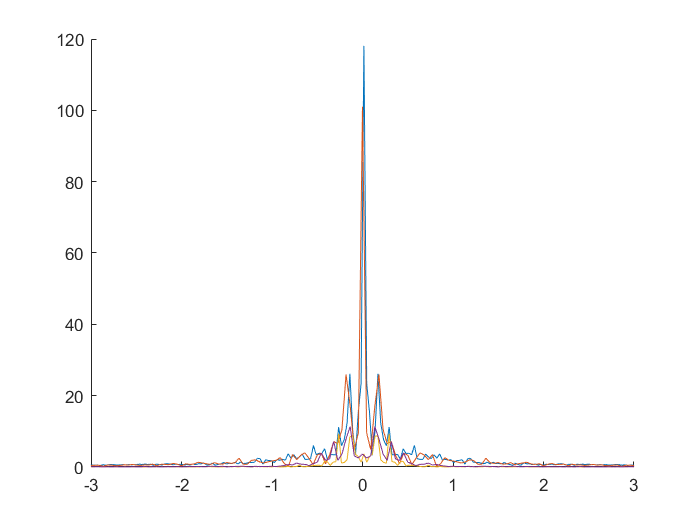

% dft of handle acceleration of good rowing section
fs = 50;        % sampling frequency
N = length(normal_handle_good);

dft_handle_good = fftshift(abs(fft(normal_handle_good)));
frequencies = linspace(-fs/2, fs/2, N);

clf; hold on;
plot(frequencies, dft_handle_good/N)
xlim([-3 3])


% dft of handle acceleration of good rowing section
N = length(normal_handle_bad);

dft_handle_bad = fftshift(abs(fft(normal_handle_bad)));
frequencies = linspace(-fs/2, fs/2, N);

plot(frequencies, dft_handle_bad/N);


% dft of seat acceleration of good rowing section
N = length(normal_seat_good);

dft_seat_good = fftshift(abs(fft(normal_seat_good)));
frequencies = linspace(-fs/2, fs/2, N);

plot(frequencies, dft_seat_good/N);


% dft of seat acceleration of bad rowing section
N = length(normal_seat_bad);

dft_seat_bad = fftshift(abs(fft(normal_seat_bad)));
frequencies = linspace(-fs/2, fs/2, N);

plot(frequencies, dft_seat_bad/N);